## Benchmark of RAT Bayes Calculation

Start with a direct calculation of the posteriors for a simple problem. We use a simple reflectivity from D2O, and fit only two parameters - Roughness and background. 

The task is to calculate chi-squared on a 2D grid, with one axis representing roughness and the other background. For each pair of values, the likelihood is given by

 $P\propto\exp \left(-\frac{\chi^2 }{2}\right)$ . 

We calculate this on a grid, and this then gives the benchmark posterior distributions which can then be used to validate the two Bayes algorithms included in RAT.

1. **Calculation of 2D posterior.**

Start by setting up the problemDef and controlsDef input classes. We do this by converting from a RasCAL1 project.

problem = r1ToProjectClass('defaultProject.mat')

problem =          modelType: 'standard layers'
    experimentName: 'defaultProject'
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min         Value          Max    Fit? 
    _    _____________________    ___    ________________    ___    _____

    1    "Substrate Roughness"     3     4.84436313284922     8     true 


    Bulk In: -------------------------------------------------------------------------------------------------- 

    p    Name     Min    Value    Max    Fit? 
    _    _____    ___

Now we need to set up ranges for the parameters, and set up the calculation grid..

%Use a 30 x 30 grid.
%Make an array for the results...
gridSize = 30;
probArray = zeros(gridSize, gridSize);

% Make a vector of roughness values..
% Get the limits for roughness 
paramsTable = problem.parameters.varTable;
minRough = paramsTable{1,2};
maxRough = paramsTable{1,4};
roughVector = linspace(minRough, maxRough, gridSize);

%Also background...
backParsTable = problem.background.backgroundParams.varTable;
minBack = backParsTable{1,2};
maxBack = backParsTable{1,4};
backsVector = linspace(minBack, maxBack, gridSize);

Now calculate the likelihood at all points on the grid

%Now for the calculation.
counter = 1;
totalGrid = gridSize^2;
controls = controlsClass();
controls.procedure = 'calculate';
controls.display = 'off';
tic;
f = waitbar(0,'Calculating:','Name','Progress:');
for r = 1:gridSize
    for b = 1:gridSize
        thisRough = roughVector(r);
        thisBack =  backsVector(b);
        
        problem.setParameter(1,'value',thisRough);
        problem.setBackgroundParam(1,'value',thisBack);
        
        [outProblem,results] = RAT(problem,controls);
        thisChi = results.calculationResults.sumChi;
        probArray(r,b) = exp(-thisChi/2);
        percent = (counter/totalGrid);
        %fprintf('Calculated %1.1f percent \n',percent);
        waitbar(percent,f);
        counter = counter + 1;
    end
end
close(f);
toc;

Elapsed time is 0.055676 seconds.


We can now plot this to see the resulting 2D posterior....

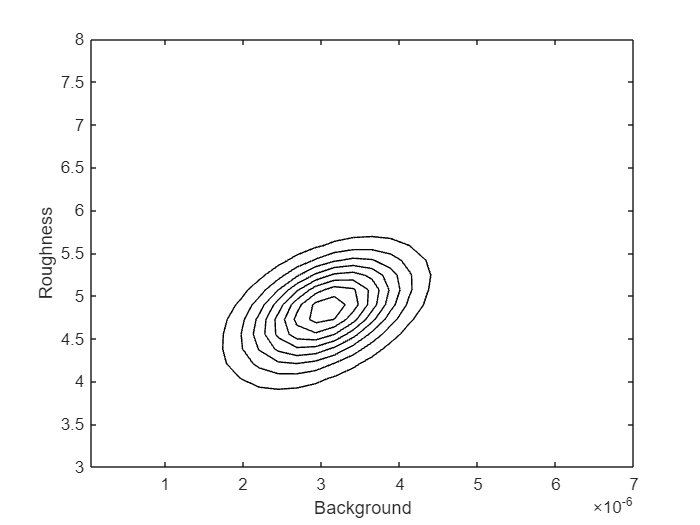

figure
contour(backsVector,roughVector,probArray,'k-');
hold on
xlabel('Background');
ylabel('Roughness')

We can now calculate the individual posterior distributions by margnalising along the other dimension. For roughness we sum over columns..

roughDist = sum(probArray,1);   % Sum over columns
backsDist = sum(probArray,2);   % Sum over rows

Normalise each distribution by simply dividing by the maximum value.

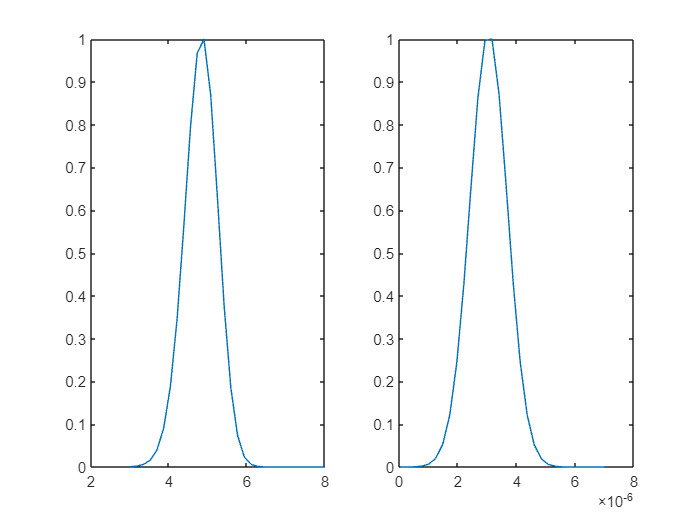

roughDist = roughDist ./ max(roughDist);
backsDist = backsDist ./ max(backsDist);

roughPosterior = [roughVector(:) backsDist(:)];
backsPosterior = [backsVector(:) roughDist(:)];

subplot(1,2,1);
plot(roughPosterior(:,1), roughPosterior(:,2));
subplot(1,2,2); 
plot(backsPosterior(:,1), backsPosterior(:,2));

### 2. DREAM...

Now run the analysis using DRAM, and compare the resulting posteriors to the calculated ones.

problem.setScalefactor(1,'fit',false);

controls.procedure = 'dream';
controls.nSamples = 25000;
tic;
[outProb,results] = RAT(problem,controls);
toc

Elapsed time is 2.152821 seconds.


We can get the posteriors from results.chain...

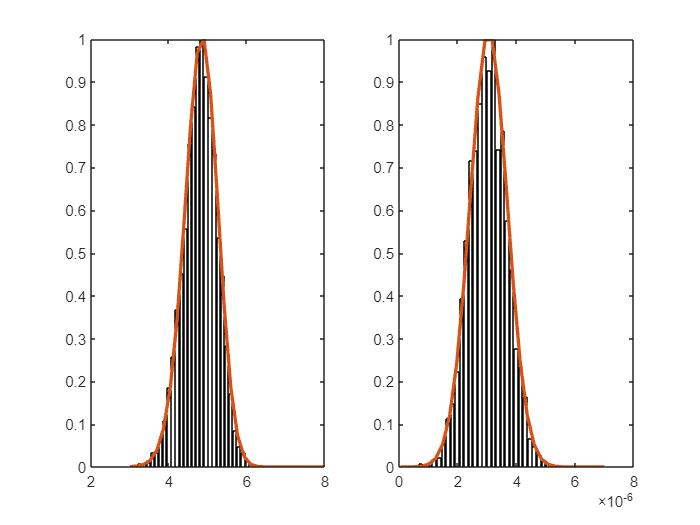

roughPostDram = results.chain(:,1);
backPostDram = results.chain(:,2);

[roughCounts,roughBins] = hist(roughPostDram,30);
roughCounts = roughCounts ./ max(roughCounts);

[backCounts,backBins] = hist(backPostDram,30);
backCounts = backCounts ./ max(backCounts);

subplot(1,2,1); bar(roughBins,roughCounts,'w');
hold on; plot(roughPosterior(:,1), roughPosterior(:,2), 'LineWidth', 2.0)
subplot(1,2,2); bar(backBins,backCounts,'w');
hold on; plot(backsPosterior(:,1), backsPosterior(:,2), 'LineWidth',2.0);

## 3. Nested Sampling

Nested sampling is primarily for model selection, but can be used to obtain the posteriors also. We do the same comparison as for DRAM.

In order to switch to NS, we just need to change the relevant flag in controlsDef...

controls.procedure = 'NS';
controls.nLive = 200

controls =   controlsClass with properties:

            parallel: 'single'
           procedure: 'ns'
    calcSldDuringFit: 0
             display: 'off'
               nLive: 200
               nMCMC: 0
           propScale: 0.100000000000000
         nsTolerance: 0.100000000000000
      resampleParams: [0.900000000000000 50]


.. and run RAT..

tic;
[outNS,results] = RAT(problem,controls)

outNS =          modelType: 'standard layers'
    experimentName: 'defaultProject'
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min         Value          Max    Fit? 
    _    _____________________    ___    ________________    ___    _____

    1    "Substrate Roughness"     3     4.80919408246332     8     true 


    Bulk In: -------------------------------------------------------------------------------------------------- 

    p    Name     Min    Value    Max    Fit? 
    _    _____    ___  

results = struct with fields:
           reflectivity: {[53×2 double]}
             simulation: {[53×2 double]}
            shiftedData: {[53×3 double]}
              layerSlds: {[0 0 0]}
            sldProfiles: {[151×2 double]}
        resampledLayers: {[0 0 0]}
     calculationResults: [1×1 struct]
         contrastParams: [1×1 struct]
              fitParams: [4.809194082463324 3.028372918498087e-06]
               fitNames: {2×1 cell}
    predictionIntervals: [1×1 struct]
    confidenceIntervals: [1×1 struct]
            dreamParams: [1×1 struct]
            dreamOutput: [1×1 struct]
    nestedSamplerOutput: [1×1 struct]
                  chain: [527×2 double]


toc

Elapsed time is 0.484702 seconds.


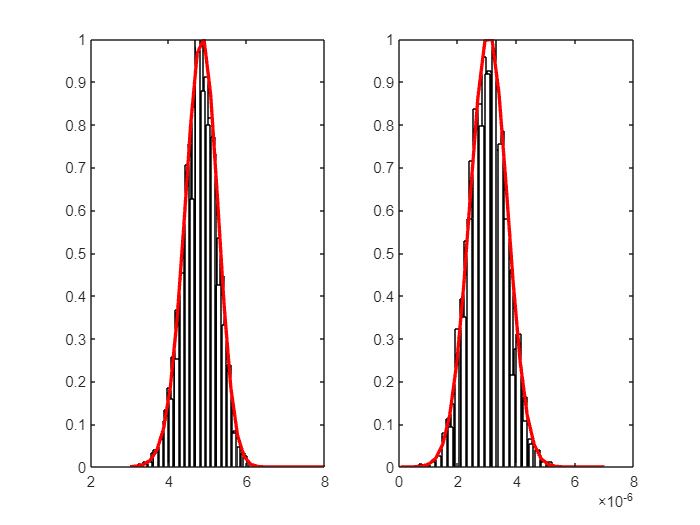

posteriors = results.nestedSamplerOutput.postSamples;
roughPostNS = posteriors(:,1);
backPostNS = posteriors(:,2);

[roughCountsNS,roughBinsNS] = hist(roughPostNS,20);
roughCountsNS = roughCountsNS ./ max(roughCountsNS);

[backCountsNS,backBinsNS] = hist(backPostNS,20);
backCountsNS = backCountsNS ./ max(backCountsNS);

subplot(1,2,1); bar(roughBinsNS,roughCountsNS,'w');
hold on; plot(roughPosterior(:,1), roughPosterior(:,2),'r-', 'LineWidth', 2.0)
subplot(1,2,2); bar(backBinsNS,backCountsNS,'w');
hold on; plot(backsPosterior(:,1), backsPosterior(:,2),'r-', 'LineWidth',2.0);

## 3. Overall Comparison

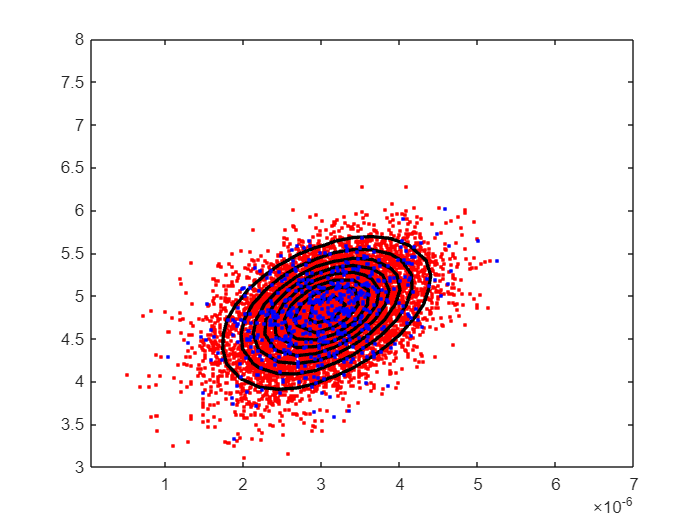

figure

hold on; box on

plot(backPostDram,roughPostDram,'r.')
contour(backsVector,roughVector,probArray,'k-','LineWidth',2);
plot(backPostNS,roughPostNS,'b.')